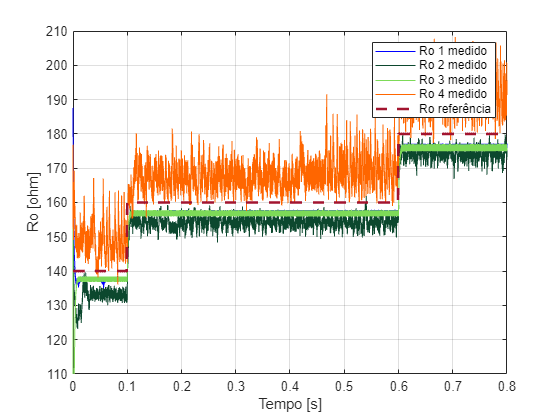

load("results_modo1.mat")

Vco1 = out.Vok.signals(1).values;
rok1 = out.Rok.signals(1).values;

load("results_modo2.mat")

Vco2 = out.Vok.signals(1).values;
rok2 = out.Rok.signals(1).values;

load("results_modo3.mat")

Vco3 = out.Vok.signals(1).values;
rok3 = out.Rok.signals(1).values;

load("results_modo4.mat")

Vco4 = out.Vok.signals(1).values;
rok4 = out.Rok.signals(1).values;

Vco_ref = out.Vok.signals(2).values;
rok_ref = out.Rok.signals(2).values;
t = linspace(0,0.8,length(Vco1));


plot(t,rok1,"Color","b","DisplayName","Ro 1 medido")
hold on
plot(t,rok2,"Color","#0c482e","DisplayName","Ro 2 medido")
plot(t,rok3,"Color","#7DDA58","DisplayName","Ro 3 medido")
plot(t,rok4,"Color","#ff6600","DisplayName","Ro 4 medido")
plot(t, rok_ref,'--','LineWidth',2,"Color","#A2142F","DisplayName","Ro referência")
hold off
xlabel("Tempo [s]")
ylabel("Ro [ohm]")
axis([0 0.8 110 210])
legend
grid

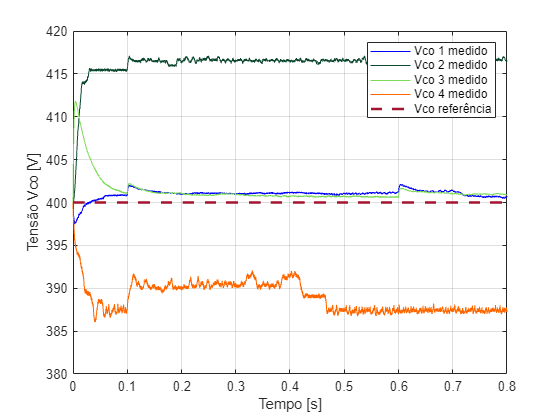


plot(t,Vco1,"Color","b","DisplayName","Vco 1 medido")
hold on
plot(t,Vco2,"Color","#0c482e","DisplayName","Vco 2 medido")
plot(t,Vco3,"Color","#7DDA58","DisplayName","Vco 3 medido")
plot(t,Vco4,"Color","#ff6600","DisplayName","Vco 4 medido")
plot(t,Vco_ref,'--','LineWidth',2,"Color","#A2142F","DisplayName","Vco referência")
hold off
xlabel("Tempo [s]")
ylabel("Tensão Vco [V]")
axis([0 0.8 380 420])
legend

grid


m1 = Vco1(1:10000);
m2 = Vco1(10001:60000);
m3 = Vco1(60001:80000);
d1 = peak2peak(Vco1(1:10000));
d2 = peak2peak(Vco1(10001:60000));
d3 = peak2peak(Vco1(60001:80000));


disp("REF  " + "Media     " + "EMRP  " + "   Delta ");

REF  Media     EMRP     Delta 


disp("400  " +mean(m1)+ "  "+ 100*(mean(m1) - 400)/400 + "  " + d1)

400  400.1226  0.03064  3.4525


disp("400  " +mean(m2)+ "  "+ 100*(mean(m2) - 400)/400 + "  " + d2)

400  401.1302  0.28256  1.2349


disp("400  " +mean(m3)+ "  "+ 100*(mean(m3) - 400)/400 + "  " + d3)

400  401.136  0.28399  1.7081



m1 = Vco2(1:10000);
m2 = Vco2(10001:60000);
m3 = Vco2(60001:80000);
d1 = peak2peak(Vco2(1:10000));
d2 = peak2peak(Vco2(10001:60000));
d3 = peak2peak(Vco2(60001:80000));


disp("REF  " + "Media     " + "EMRP  " + "   Delta ");

REF  Media     EMRP     Delta 


disp("400  " +mean(m1)+ "  "+ 100*(mean(m1) - 400)/400 + "  " + d1)

400  413.89  3.4725  15.9585


disp("400  " +mean(m2)+ "  "+ 100*(mean(m2) - 400)/400 + "  " + d2)

400  416.5753  4.1438  1.6134


disp("400  " +mean(m3)+ "  "+ 100*(mean(m3) - 400)/400 + "  " + d3)

400  416.6603  4.1651  0.8832



m1 = Vco3(1:10000);
m2 = Vco3(10001:60000);
m3 = Vco3(60001:80000);
d1 = peak2peak(Vco3(1:10000));
d2 = peak2peak(Vco3(10001:60000));
d3 = peak2peak(Vco3(60001:80000));


disp("REF  " + "Media     " + "EMRP  " + "   Delta ");

REF  Media     EMRP     Delta 


disp("400  " +mean(m1)+ "  "+ 100*(mean(m1) - 400)/400 + "  " + d1)

400  404.174  1.0435  12.2557


disp("400  " +mean(m2)+ "  "+ 100*(mean(m2) - 400)/400 + "  " + d2)

400  400.8961  0.22402  1.708


disp("400  " +mean(m3)+ "  "+ 100*(mean(m3) - 400)/400 + "  " + d3)

400  401.1121  0.27802  1.0939



m1 = Vco4(1:10000);
m2 = Vco4(10001:60000);
m3 = Vco4(60001:80000);
d1 = peak2peak(Vco4(1:10000));
d2 = peak2peak(Vco4(10001:60000));
d3 = peak2peak(Vco4(60001:80000));


disp("REF  " + "Media     " + "EMRP  " + "   Delta ");

REF  Media     EMRP     Delta 


disp("400  " +mean(m1)+ "  "+ 100*(mean(m1) - 400)/400 + "  " + d1)

400  389.0553  -2.7362  13.966


disp("400  " +mean(m2)+ "  "+ 100*(mean(m2) - 400)/400 + "  " + d2)

400  389.509  -2.6227  5.3796


disp("400  " +mean(m3)+ "  "+ 100*(mean(m3) - 400)/400 + "  " + d3)

400  387.4008  -3.1498  1.2592






% i1 = rok1(1:10000);
% i2 = rok1(10001:60000);
% i3 = rok1(60001:80000);
% d1 = peak2peak(rok1(1:10000));
% d2 = peak2peak(rok1(10001:60000));
% d3 = peak2peak(rok1(60001:80000));
% 
% 
% disp("REF  " + "Media     " + "EMRP  " + "   Delta ");
% disp("140  " +mean(i1)+ "  "+ 100*(mean(i1) - 140)/140 + "  " + d1)
% disp("160  " +mean(i2)+ "  "+ 100*(mean(i2) - 160)/160 + "  " + d2)
% disp("180  " +mean(i3)+ "  "+ 100*(mean(i3) - 180)/180 + "  " + d3)
% 
% i1 = rok2(1:10000);
% i2 = rok2(10001:60000);
% i3 = rok2(60001:80000);
% d1 = peak2peak(rok2(1:10000));
% d2 = peak2peak(rok2(10001:60000));
% d3 = peak2peak(rok2(60001:80000));
% 
% 
% disp("REF  " + "Media     " + "EMRP  " + "   Delta ");
% disp("140  " +mean(i1)+ "  "+ 100*(mean(i1) - 140)/140 + "  " + d1)
% disp("160  " +mean(i2)+ "  "+ 100*(mean(i2) - 160)/160 + "  " + d2)
% disp("180  " +mean(i3)+ "  "+ 100*(mean(i3) - 180)/180 + "  " + d3)
% 
% i1 = rok4(1:10000);
% i2 = rok4(10001:60000);
% i3 = rok4(60001:80000);
% d1 = peak2peak(rok4(1:10000));
% d2 = peak2peak(rok4(10001:60000));
% d3 = peak2peak(rok4(60001:80000));
% 
% 
% disp("REF  " + "Media     " + "EMRP  " + "   Delta ");
% disp("140  " +mean(i1)+ "  "+ 100*(mean(i1) - 140)/140 + "  " + d1)
% disp("160  " +mean(i2)+ "  "+ 100*(mean(i2) - 160)/160 + "  " + d2)
% disp("180  " +mean(i3)+ "  "+ 100*(mean(i3) - 180)/180 + "  " + d3)